f = @(x) x.^2 - 4*x + 3.5;
r = roots([1 -4 3.5]);

Here is the fixed point iteration. This time we keep track of the whole sequence of approximations. 

g = @(x) x - f(x);
x = 2.1; 
for k = 1:12
    x(k+1) = g(x(k));
end

It's easiest to construct and plot the sequence of errors. 

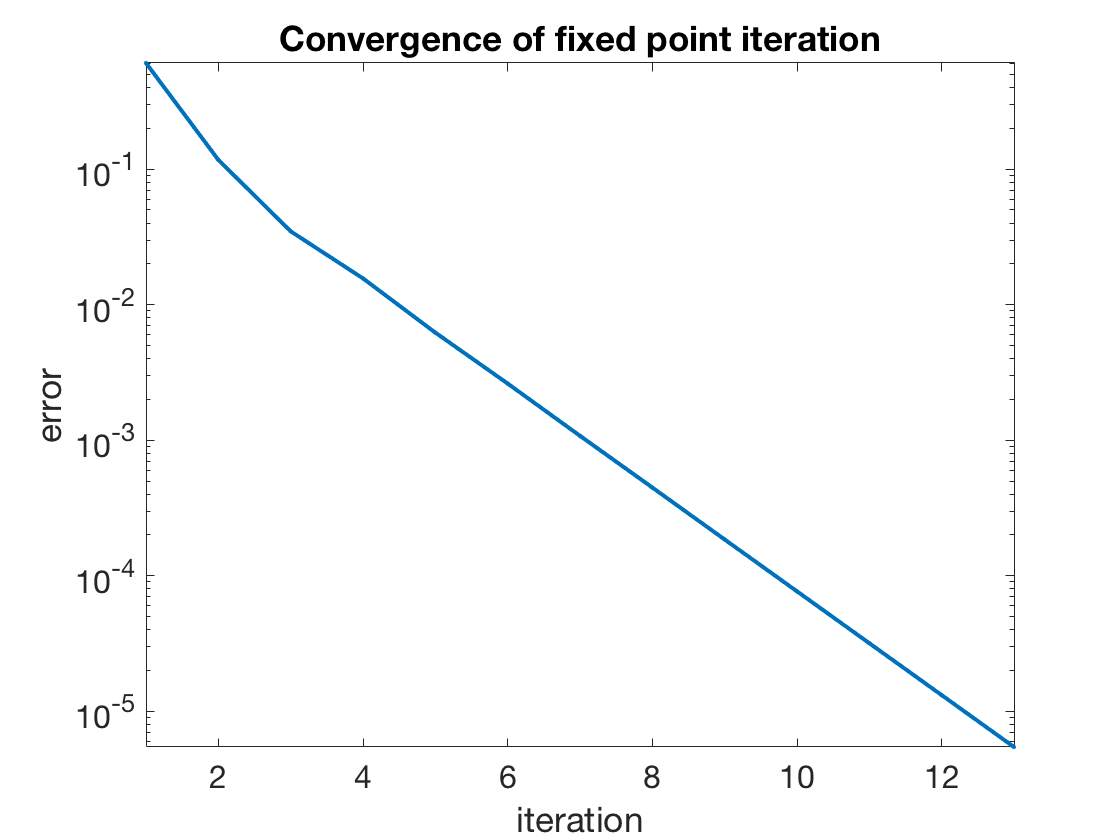

err = abs(x-r(1));
semilogy(err,'.-'), axis tight
xlabel('iteration'),  ylabel('error')
title('Convergence of fixed point iteration')

It's quite clear that the convergence quickly settles into a linear rate. We could estimate this rate by doing a least-squares fit to a straight line using MATLAB's built-in `polyfit`. Keep in mind that the values for small $k$ should be left out of the computation, as they don't represent the linear trend. 

p = polyfit(5:12,log(err(5:12)),1)

p =   -8.8072e-01  -6.6806e-01


The first value is the slope, which must be negative. We can exponentiate it to get the convergence constant $\sigma$.

sigma = exp(p(1))

sigma =    4.1449e-01


The numerical values of the error should decrease by a factor of $\sigma$ at each iteration. We can check this easily with an elementwise division.

err(9:12) ./ err(8:11)

ans =    4.1377e-01   4.1440e-01   4.1414e-01   4.1425e-01


The methods for finding $\sigma$ agree well.